best_acc = 0.6458

op num of layers


   101



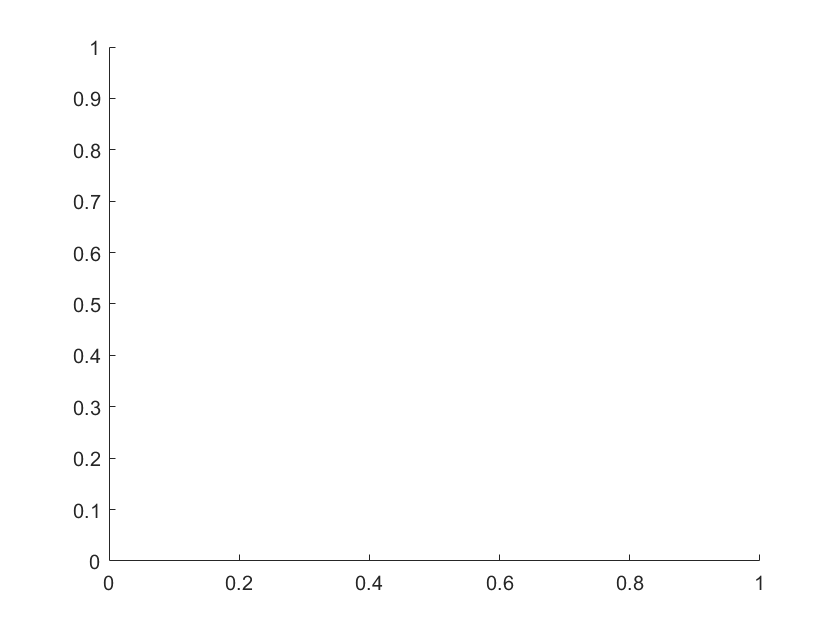

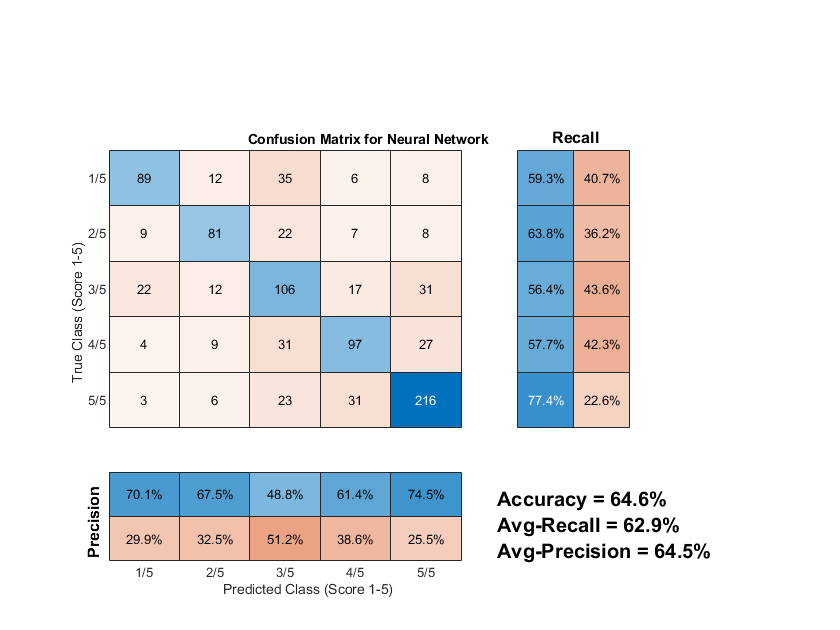

ans =   ConfusionMatrixChart (Confusion Matrix for Neural Network ) with properties:

    NormalizedValues: [5×5 double]
         ClassLabels: ["1/5"    "2/5"    "3/5"    "4/5"    "5/5"]

  Show all properties


clear;
clc;
close all;
rng(0);
load('left_arm_datawithrms.mat');
% load('left_arm_datanorms.mat');
% FeatureDataTable("max min mean std jerk",table_of_recordings,250);
% [y1, targets, datar] = RegressionNeuralNetwork(left_arm_data,10,40,70,15,15,true);
    best_acc = 0;
     for opnumoflayers = 5:171
[classes, targetvals, datac, ytst, ttst] = ClassificationNeuralNetwork(left_arm_data,opnumoflayers,70,30,false);
     [confMat,order] = confusionmat(ttst,ytst);
     metrics.overall_accuracy = overall_accuracy(confMat);
     if metrics.overall_accuracy > best_acc
         best_acc = metrics.overall_accuracy
         best = opnumoflayers;
     end
     disp('op num of layers')
     disp(best)

% t = tiledlayout('flow');
% t.Title.String = 'Error Histogram';
% t.Padding = 'compact';
% t.TileSpacing ='compact';

% nexttile
% ErrorInfo(y1,targets)
% title('Regression Error')
% 
% nexttile
% Importance(datar,left_arm_data,'Regression ANN')

nexttile
GetClassificationEvaluation(ttst,ytst,'Neural Network')
% title('C NN')

% nexttile
% ErrorInfo(classes,targetvals)
% title('Classification Error')

% nexttile
% Importance(datac,left_arm_data, 'Classification ANN')

     end

     function y = overall_accuracy(M)
      y = sum(diag(M)) / sum(sum(M));
     end
 